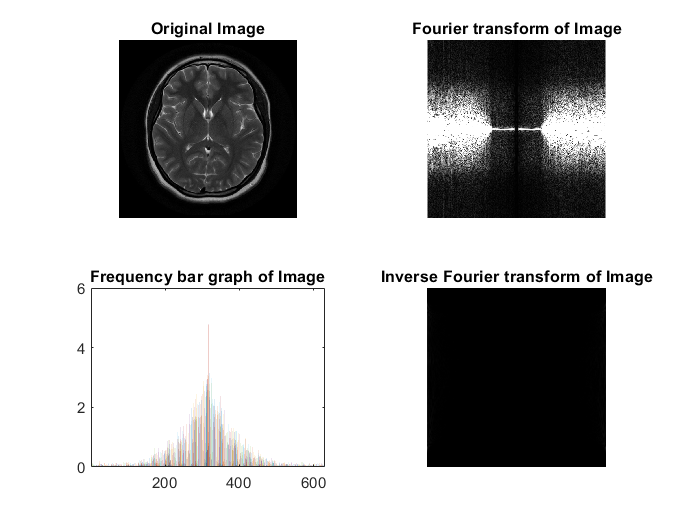

% #1
clc
clear
close all
img = imread('MRI.png');
img1 = double(mat2gray(img));
imgF = fftshift(fft(img1));
I = log(1+abs(imgF));
subplot(2,2,1);
imshow(img);
title('Original Image')
subplot(2,2,2);
imshow(I)
title('Fourier transform of Image')
subplot(2,2,3);
bar(I)
title('Frequency bar graph of Image')
imginv = abs(ifft2(imgF));
subplot(2,2,4);
imshow(imginv)
title('Inverse Fourier transform of Image')

% #2
grayIm = imread('MRI.png');
[row col] = size(grayIm);
subplot(2, 2, 1);
imshow(grayIm);
title('original image')
A=fft2(grayIm); %2D fft
count_pic=2;
for thresh=0.1*[0.001 0.005 0.006]*max(max(abs(A)))
    ind=abs(A)>thresh;
    count=row*col-sum(sum(ind));
    Alow=A.*ind;
    per=100-count/(row*col)*100;
    
    Blow=uint8(ifft2(Alow)); 
    subplot(2,2,count_pic);
    imshow(Blow);
    count_pic=count_pic+1;
    title([num2str(per) '% of fft basis'])
end

% #3
clc
clear
close all
img = imread('MRI.png');
I = im2double(img);
I = I(:,:,1);
k = dctmtx(8);
B = blkproc(I, [0 0], 'P1*x*P2', k, k');

Error using zeros
NaN and Inf not allowed.

Error in blkproc (line 88)
        aa = zeros(ma+mpad+2*border(1),na+npad+2*border(2));

imshow(B)

% #4
a = imread('MRI.png');
ad = dct2(a)
h = imagesc(ad)
impixelregion(h)
